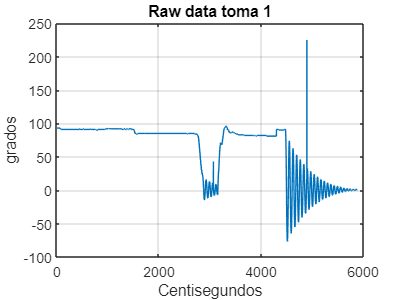

%Cargar los vectores
angle01 = load("Raw_angle01.txt");
angle02 = load("Raw_angle02.txt");

%Su vector en X está en centésimas de segundo
L01 = length(angle01);
L02 = length(angle02);
t01 = [1:1:L01]';
t02 = [1:1:L02]';

plot(t01, angle01)
title('Raw data toma 1')
xlabel('Centisegundos')
ylabel('grados')
grid on

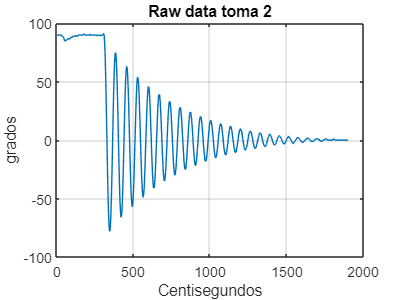

plot(t02, angle02)
title('Raw data toma 2')
xlabel('Centisegundos')
ylabel('grados')
grid on

## Purga

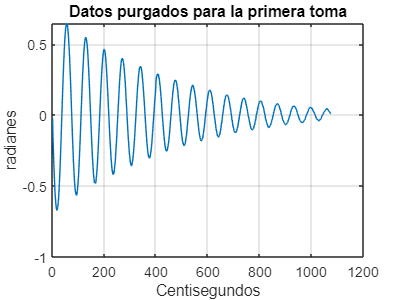


usefulA01 = cat(1, angle01(4500:4898), angle01(4900:5575));
t01 = [1:1:length(usefulA01)]';
plot(t01, usefulA01*pi/360)
title('Datos purgados para la primera toma')
xlabel('Centisegundos')
ylabel('radianes')
grid on

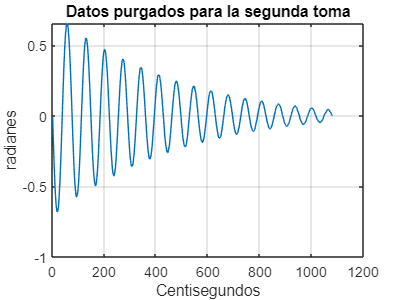


usefulA02 = angle02(327:1407);
t02 = [1:1:length(usefulA02)]';
plot(t02, usefulA02*pi/360)
title('Datos purgados para la segunda toma')
xlabel('Centisegundos')
ylabel('radianes')
grid on

## Picos

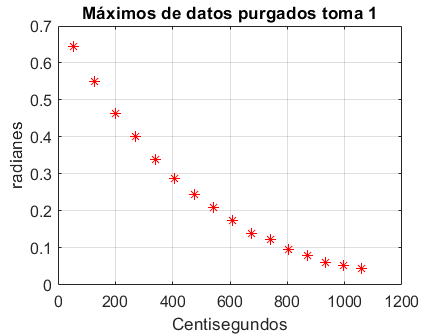

index01 = islocalmax(usefulA01);
picos01 = usefulA01(index01)*pi/360;
tiempo01 = t01(index01);
plot(tiempo01, picos01, 'r*')
grid on
title('Máximos de datos purgados toma 1')
xlabel('Centisegundos')
ylabel('radianes')

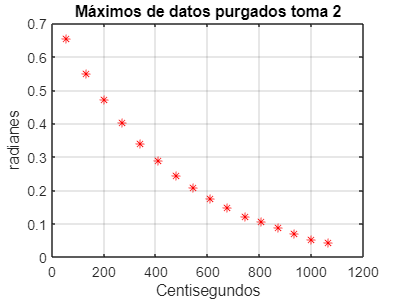


index02 = islocalmax(usefulA02);
picos02 = usefulA02(index02)*pi/360;
tiempo02 = t02(index02);
plot(tiempo02, picos02, 'r*')
grid on
title('Máximos de datos purgados toma 2')
xlabel('Centisegundos')
ylabel('radianes')

## Regresión

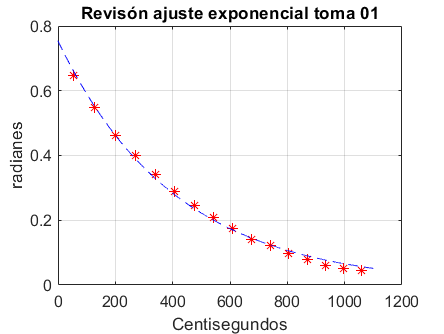

%Regresión exponencial 1
exp1 = fit(tiempo01,picos01,'exp1');

%Graficamos nuevamente los picos
f1 = figure();
plot(tiempo01, picos01, 'r*')
grid on
title('Revisón ajuste exponencial toma 01')
xlabel('Centisegundos')
ylabel('radianes')
hold on
%Creamos un vector para probar
t_prueba = 0:0.1:1100;
%Probamos la interpolación
interpola01 = exp1.a.*exp(t_prueba.*exp1.b);
plot(t_prueba, interpola01, '--b')

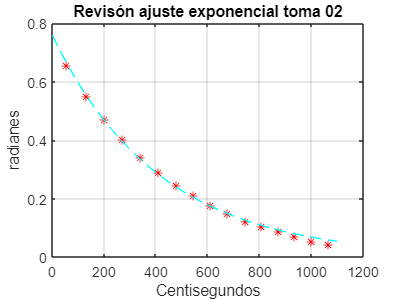


%Regresión exponencial 2
exp2 = fit(tiempo02,picos02,'exp1');

%Graficamos nuevamente los picos
f2 = figure();
plot(tiempo02, picos02, 'r*')
grid on
title('Revisón ajuste exponencial toma 02')
xlabel('Centisegundos')
ylabel('radianes')
hold on
interpola02 = exp2.a.*exp(t_prueba.*exp2.b);
plot(t_prueba, interpola02, '--c')